# Exercise 1: Getting Started: Visualize Noisy Detections 

This example uses a simple constant velocity target (simulating a piece of space debris) and simulated (noisy) radar detection data to show how we can setup a tracker and visualize how well it does in tracking the motion of space debris as it passes over the United States.

clear; clc; rng default; addpath('../HelperFunctions/')

## Exercise 1a

For this analysis, you are given a .MAT file of truth and detection data.  Load that .MAT file here:

S = load('SpaceDebrisLEO_1Target.mat');
truthPosition = S.truthPos;     % Truth Position - where the target actually is
detectionPosition = S.detPos;   % Detection Position - where the target was detected
time = S.time;                  % Time
measurementNoise = S.objDet{1}.MeasurementNoise; % Measurement Noise

Leverage the Sensor Fusion and Tracking plotter tools to visualize the truth trajectory and detections data.

### **Configure Scenario Visualization**

Create a scenario based on the Truth Data, so that we can visualize the tracker.

Directions:

Below, please create a variable 'tp' that holds a 'theaterPlot' object with default settings. 

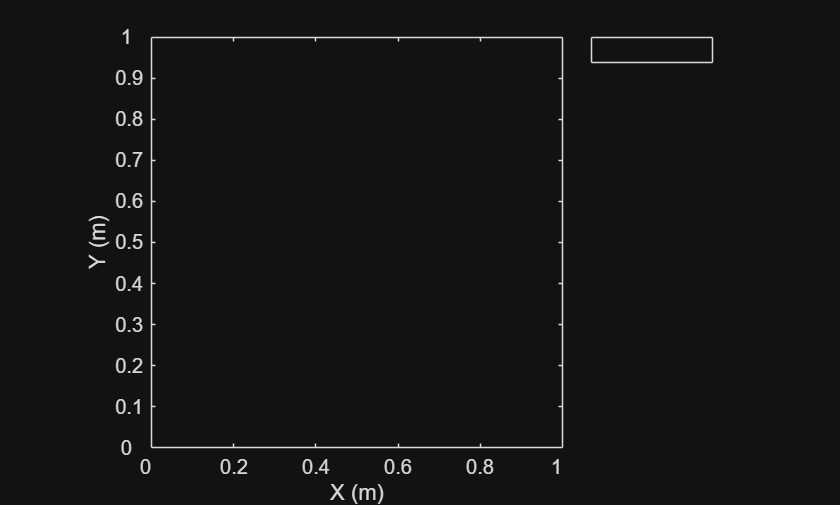

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% WRITE YOUR CODE HERE:
% type "doc theaterPlot" in the Command Window to find the documentation page for this function
tp = theaterPlot();

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

The code below uses plotter objects to plot the truth trajectory and simulated detections in the theaterplot object you created above. Create plotter objects:

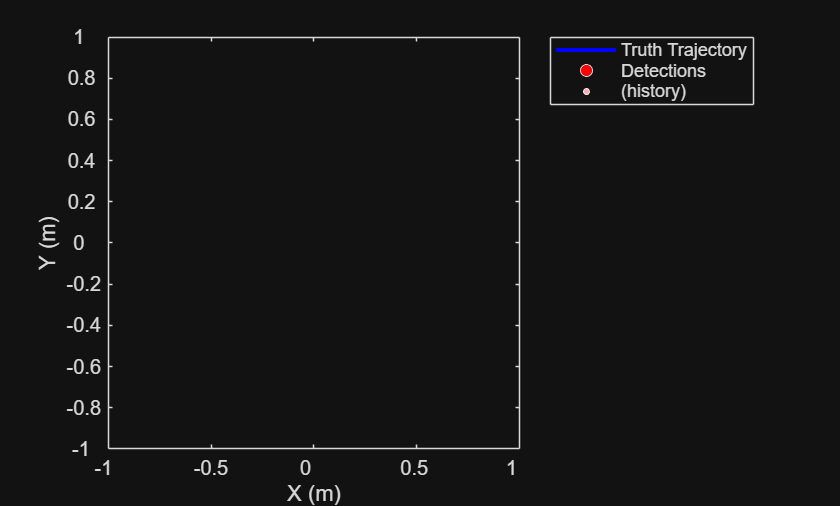

trajPlotter = trajectoryPlotter(tp,'DisplayName','Truth Trajectory','LineWidth',2,'LineStyle','-','Color','b');
detPlotter = detectionPlotter(tp,'HistoryDepth',1e3,'DisplayName','Detections','MarkerFaceColor','r');

Plot Truth Trajectory

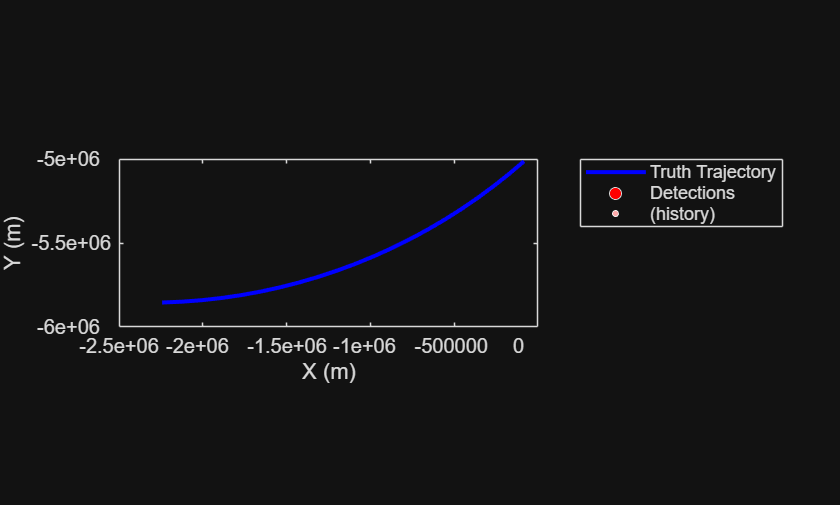

plotTrajectory(trajPlotter,{truthPosition'})

Adjust the figure window and add a legend.

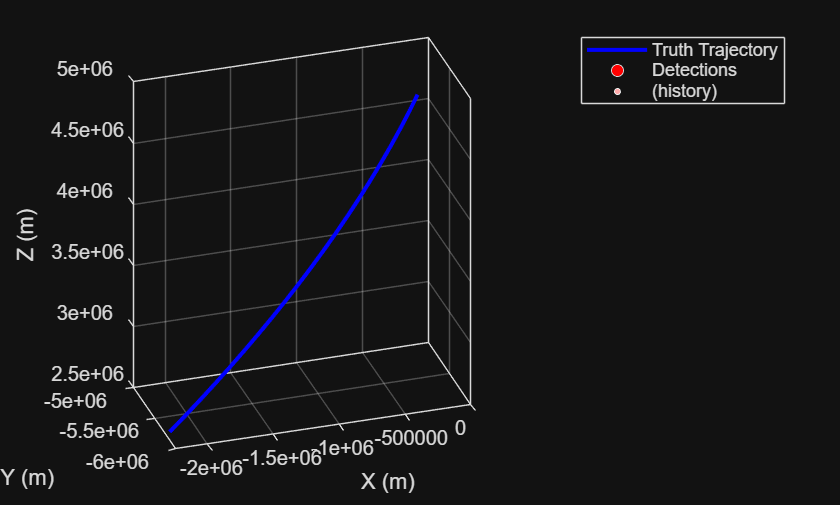

grid on, box on; legend(gca,'Location','northwest')
view(-18,28)

Plot Detections Loop plots the detections in an "as sensor detects target" fashion

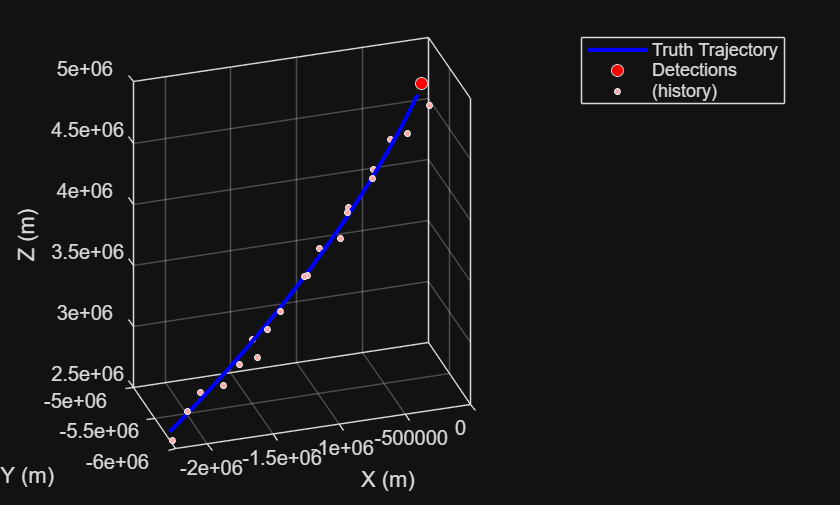

for n = 1:length(time)
    % Plot Position of Current Detection 
    plotDetection(detPlotter,detectionPosition(:,n)')
    
    % Draw Detections During Each Loop
    drawnow
end

# **Takeaways:**

We were able to visualize the trajectory of a single piece of space debris using the Sensor Fusion and Tracking tools. These tools make it easier to plot covariance ellipsoids, keeps track of truth and detection data for you, and make clean plots with default settings. This will help us to test out our tracking algorithms in the future exercises.

**BONUS #1 - Plot Detection Covariance Ellipsoid**

Add a third input "measurementNoise" to the call to plotDetection to plot the covariance ellipsoid associated with the measurement noise. For more information on syntax, type "doc plotDetection" in the Command Window and look for "covariances".

**BONUS #2 - Plot Current Position**

Add an additional call to "plotDetection" to plot the current truth position along the truth trajectory. 

We have already given you the detectionPlotter above stored in "trajPtPlotter" for the truth position. Now, within the Plot Detections loop (anywhere between the "for" and "end" lines), add a call to "plotDetections" that takes "trajPtPlotter" as the first input and "truthPosition(:,n)' " as the second input.  

For more information type "plotDetection" in the Command Window.

*NOTE: you need to transpose the the truthPosition to conform to the expected input format, so the apostrophe in the explanation above is needed.*